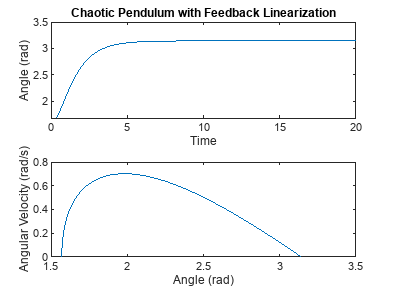

clc;
close all; 
clear

%% Feedback Control of Chaotic Systems

% Define the chaotic pendulum system
f = @(t,x) [x(2); -sin(x(1))];

% Set initial conditions
x0 = [pi/2; 0];

% Define the feedback control law
K = [-2 -2];

% Define the feedback linearization function
g = @(x) K(1)*(x(1)-pi) + K(2)*x(2);

% Define the simulation parameters
tspan = [0 20];
opts = odeset('RelTol',1e-6,'AbsTol',1e-8);

% Simulate the system with feedback linearization
[t,x] = ode45(@(t,x) f(t,x) + [0; g(x)], tspan, x0, opts);

% Plot the results
subplot(2,1,1)
plot(t,x(:,1))
xlabel('Time')
ylabel('Angle (rad)')
title('Chaotic Pendulum with Feedback Linearization')

subplot(2,1,2)
plot(x(:,1),x(:,2))
xlabel('Angle (rad)')
ylabel('Angular Velocity (rad/s)')

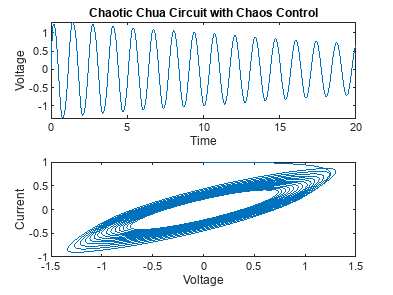


% Define the chaotic Chua circuit system
alpha = 15.6; beta = 28; m0 = -0.5; m1 = -1; m2 = -0.7;
f = @(t,x) [alpha*(x(2)-x(1)-m0*f_chua(x(1))); x(1)-x(2)+x(3); -beta*x(2)-m1*f_chua(x(1))-m2*x(3)];

% Define the chaotic control signal
g = @(t,x) -x(3);

% Simulate the system with chaos control
[t,x] = ode45(@(t,x) f(t,x) + [0; 0; g(t,x)], tspan, [0 1 1], opts);

% Plot the results
figure()
subplot(2,1,1)
plot(t,x(:,1))
xlabel('Time')
ylabel('Voltage')
title('Chaotic Chua Circuit with Chaos Control')

subplot(2,1,2)
plot(x(:,1),x(:,2))
xlabel('Voltage')
ylabel('Current')


% Define the function for the Chua circuit nonlinear function

function y = f_chua(x)
    if abs(x) <= 1
        y = x;
    elseif abs(x) > 1
        y = sign(x);
    end
end
